# A look at theoretical relative dispersion PDFs

Here we will explore some properties of the theoretical relative dispersion PDFs, with the hope that some of these might be helpful in interepreting the data.

clear all 
close all 

dr = 100; % [m]
r = 0+dr:dr:2500e3; % [m]
t = (1:100)*24*3600; % [s]

Tlung = 45*24*3600; %  [s] Time scale lungdren
beta = 20/24/3600; % [] beta for richardson
K2 = 150; % [m^/2]

r0 = 1e3; 

Plung = zeros(length(r), length(t)); 
Prich = zeros(length(r), length(t)); 
Prayl = zeros(length(r), length(t)); 

for i = 1:length(t)
    Plung(:, i) = lungdrendistfull(r, r0, t(i), Tlung, 0);
    Prich(:, i) = richdistfull(r, r0, t(i), beta, 0);
    Prayl(:, i) = rayleighdistfull(r, r0, t(i), K2, 0);
end

mom_num = [0.5, 0:5]; 
for i = 1:length(mom_num)
    lung_moments(:,i) = moments(Plung, mom_num(i), r);
    rich_moments(:,i) = moments(Prich, mom_num(i), r);
    rayl_moments(:,i) = moments(Prayl, mom_num(i), r);
end

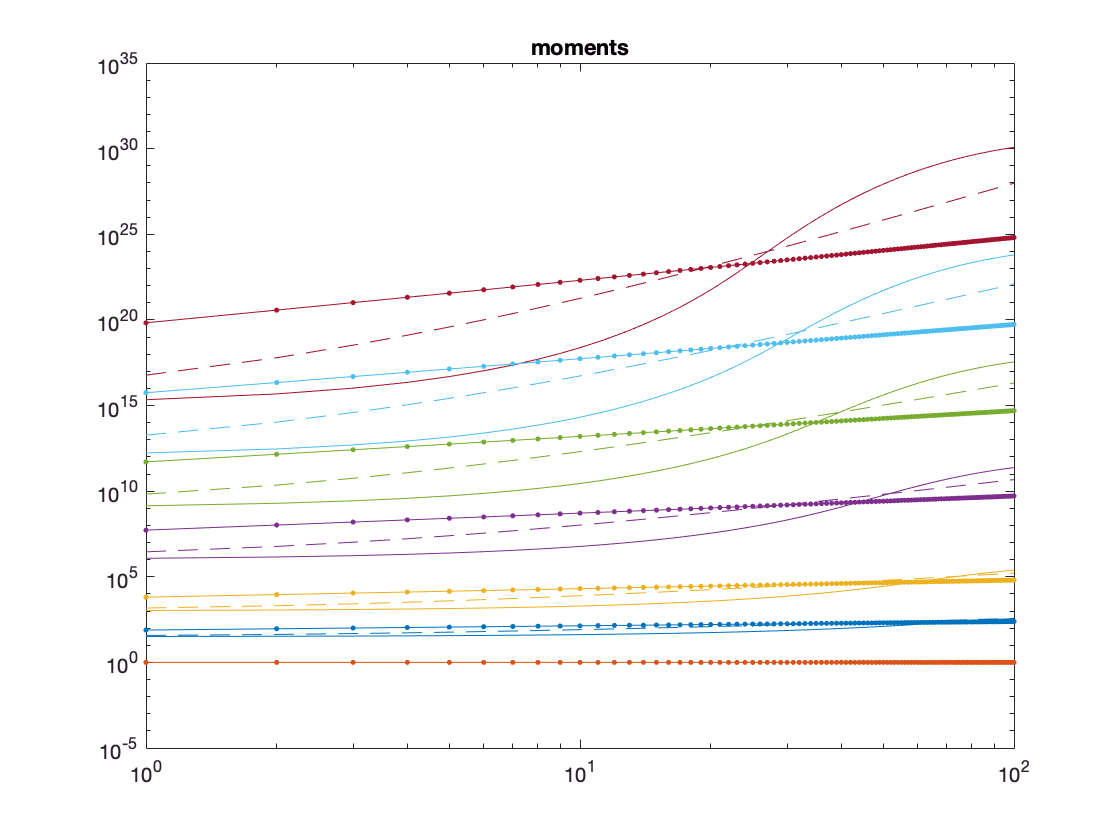


clf
loglog(t/24/3600, lung_moments)
hold all
loglog(t/24/3600, rich_moments, '--')
loglog(t/24/3600, rayl_moments, '.-')
title('moments')

mom_num

mom_num =     0.5000         0    1.0000    2.0000    3.0000    4.0000    5.0000


semilogy(t/24/3600, lung_moments(:,4)./lung_moments(:,1).^4)
hold all
semilogy(t/24/3600, rich_moments(:,4)./rich_moments(:,1).^4, '--')
semilogy(t/24/3600, rayl_moments(:,4)./rayl_moments(:,1).^4, '.-')
title('first & second')
grid on

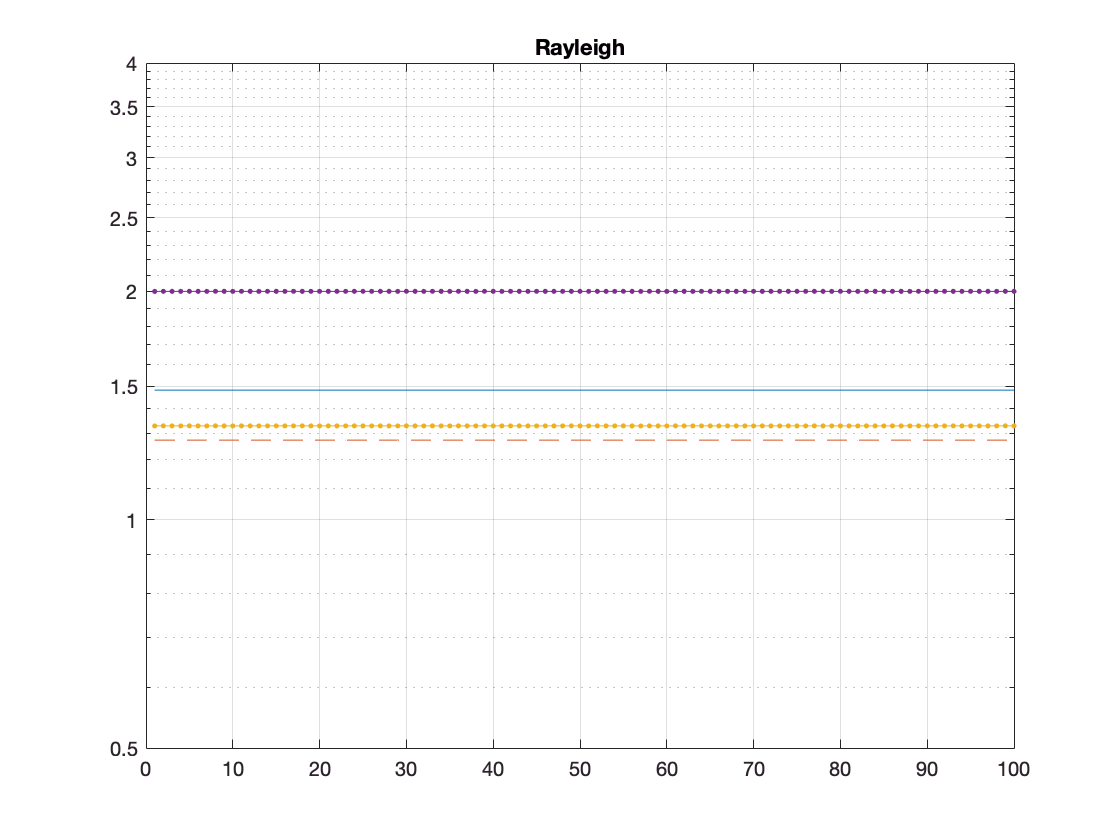

% Rayleigh 
clf
n=3; % 3 means the second moment
semilogy(t/24/3600, rayl_moments(:,4)./rayl_moments(:,1).^4)
hold all
semilogy(t/24/3600, rayl_moments(:,4)./rayl_moments(:,3).^2, '--')
semilogy(t/24/3600, rayl_moments(:,5)./rayl_moments(:,4).^(3/2), '.-')
semilogy(t/24/3600, rayl_moments(:,6)./rayl_moments(:,4).^2, '.-')
title('Rayleigh')
ylim([0.5, 4])
grid on



rayl_moments(end,4)./rayl_moments(end,3).^2

ans = 1.2732

rayl_moments(end,5)./rayl_moments(end,4).^(3/2)

ans = 1.3293

rayl_moments(end,6)./rayl_moments(end,4).^2

ans = 2.0000

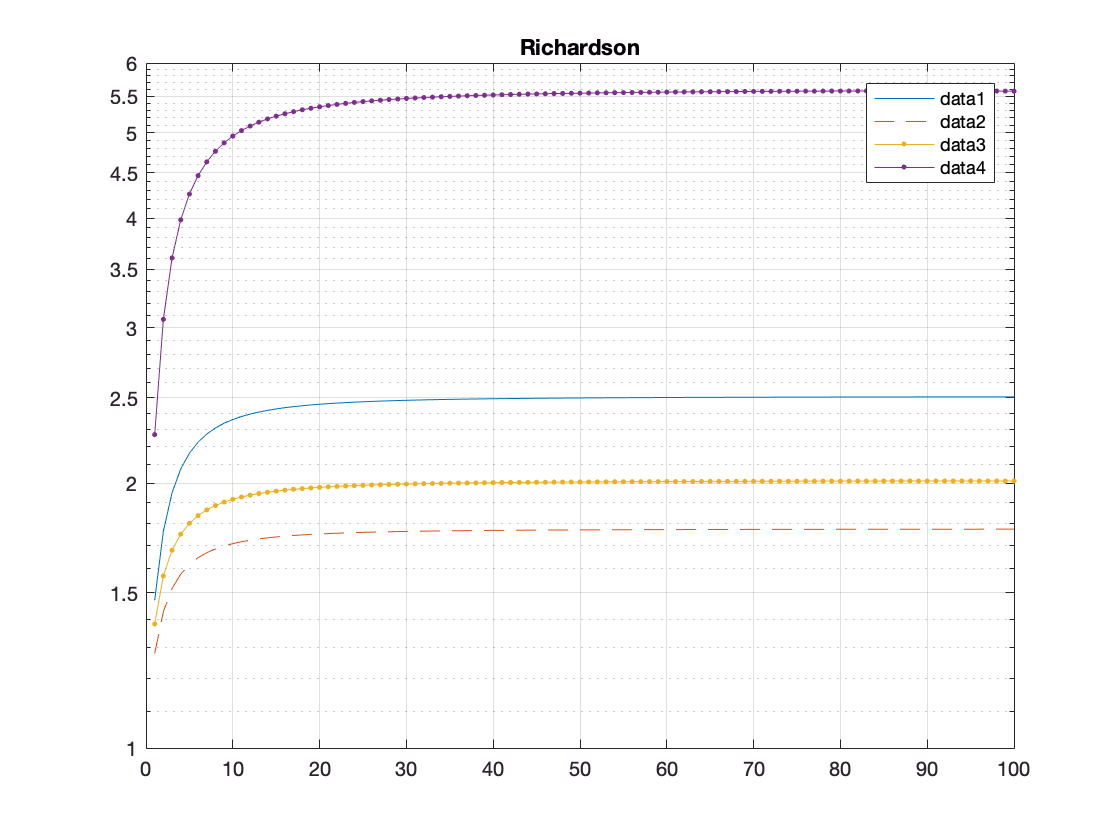

% Richardson 
clf

semilogy(t/24/3600, rich_moments(:,4)./rich_moments(:,1).^4)
hold all
semilogy(t/24/3600, rich_moments(:,4)./rich_moments(:,3).^2, '--')
semilogy(t/24/3600, rich_moments(:,5)./rich_moments(:,4).^(3/2), '.-')
semilogy(t/24/3600, rich_moments(:,6)./rich_moments(:,4).^2, '.-')
title('Richardson')
ylim([1, 6])
legend('show')
grid on


rich_moments(end,4)./rich_moments(end,3).^2

ans = 1.7725

rich_moments(end,5)./rich_moments(end,4).^(3/2)

ans = 2.0103

rich_moments(end,6)./rich_moments(end,4).^2

ans = 5.5738

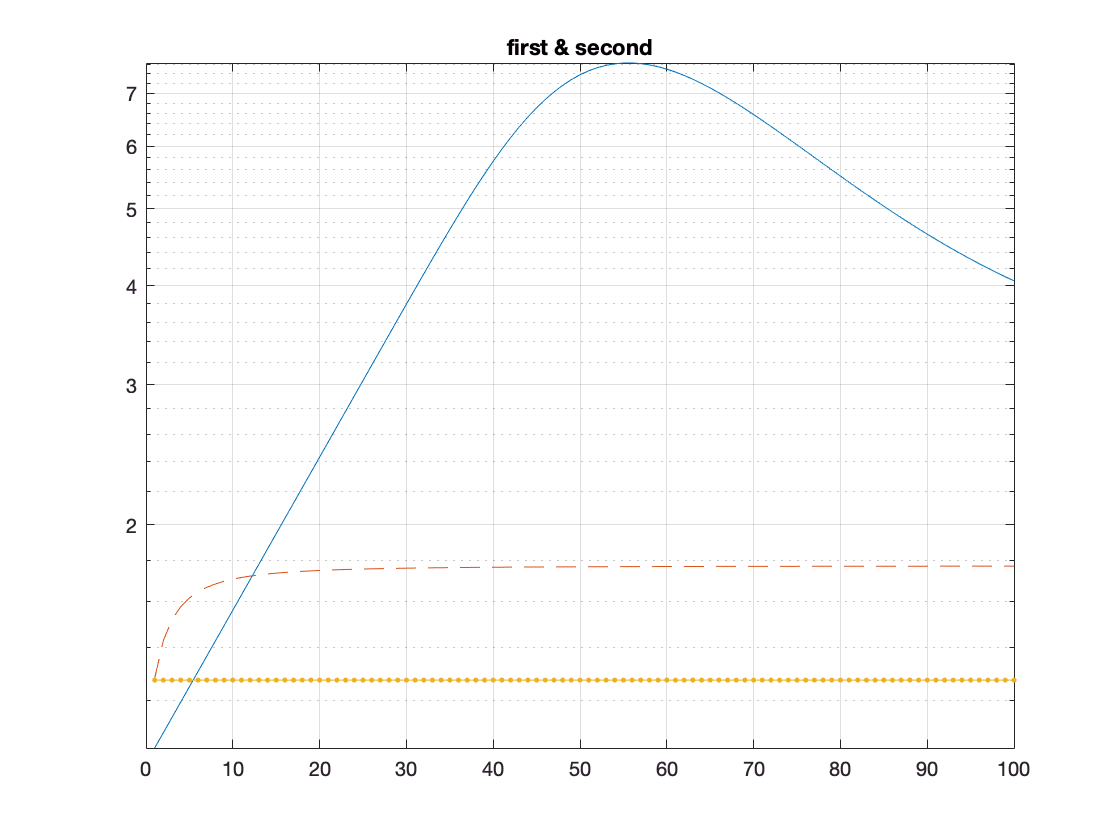

% kurtosis
clf
n=3; % 3 means the second moment
semilogy(t/24/3600, lung_moments(:,3)./lung_moments(:,2).^2)
hold all
semilogy(t/24/3600, rich_moments(:,3)./rich_moments(:,2).^2, '--')
semilogy(t/24/3600, rayl_moments(:,3)./rayl_moments(:,2).^2, '.-')
title('first & second')
grid on

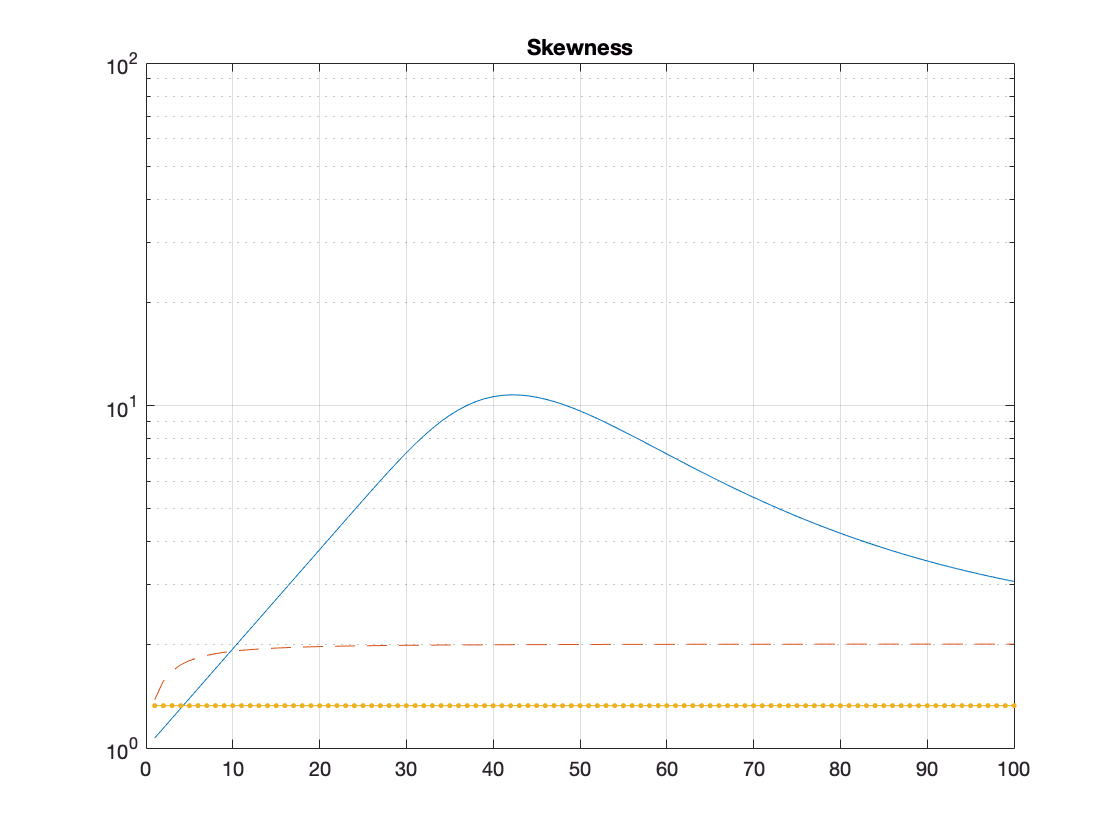

% skewness
clf
n=3; % 3 means the second moment
semilogy(t/24/3600, lung_moments(:,4)./lung_moments(:,3).^(3/2))
hold all
semilogy(t/24/3600, rich_moments(:,4)./rich_moments(:,3).^(3/2), '--')
semilogy(t/24/3600, rayl_moments(:,4)./rayl_moments(:,3).^(3/2), '.-')
title('Skewness')
grid on

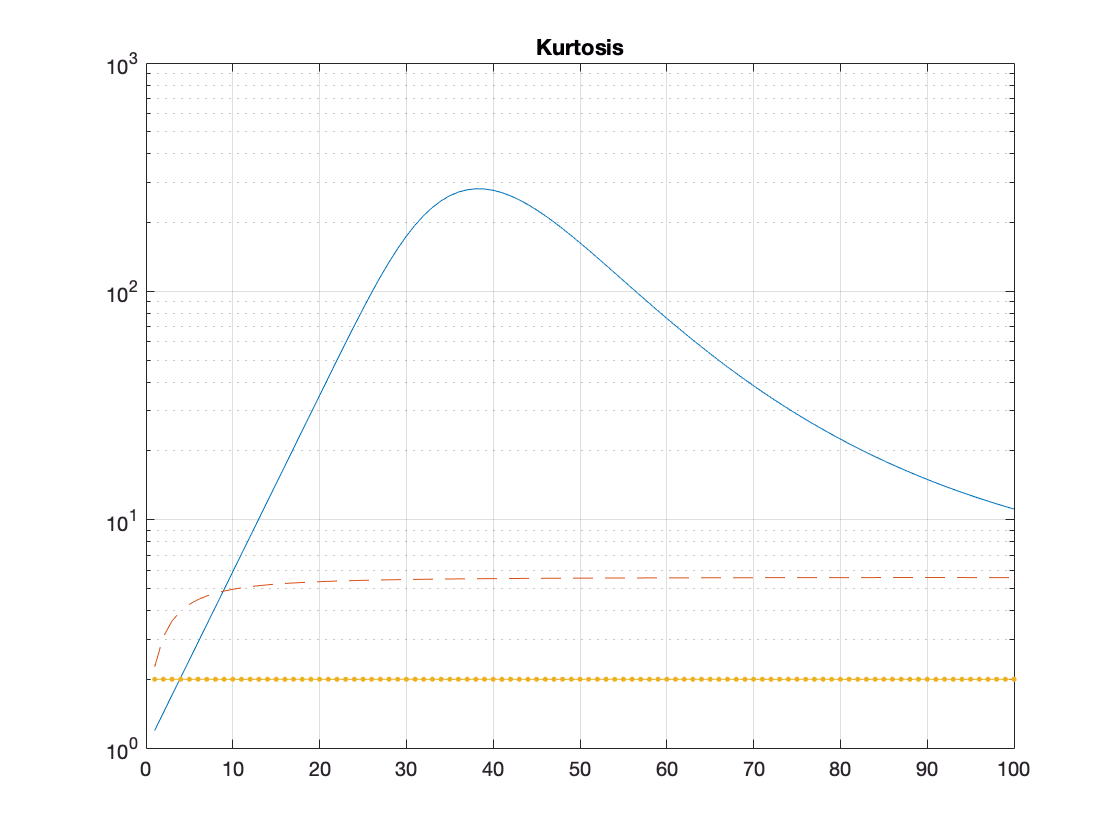

% kurtosis
clf
n=3; % 3 means the second moment
semilogy(t/24/3600, lung_moments(:,5)./lung_moments(:,3).^2)
hold all
semilogy(t/24/3600, rich_moments(:,5)./rich_moments(:,3).^2, '--')
semilogy(t/24/3600, rayl_moments(:,5)./rayl_moments(:,3).^2, '.-')
title('Kurtosis')
grid on

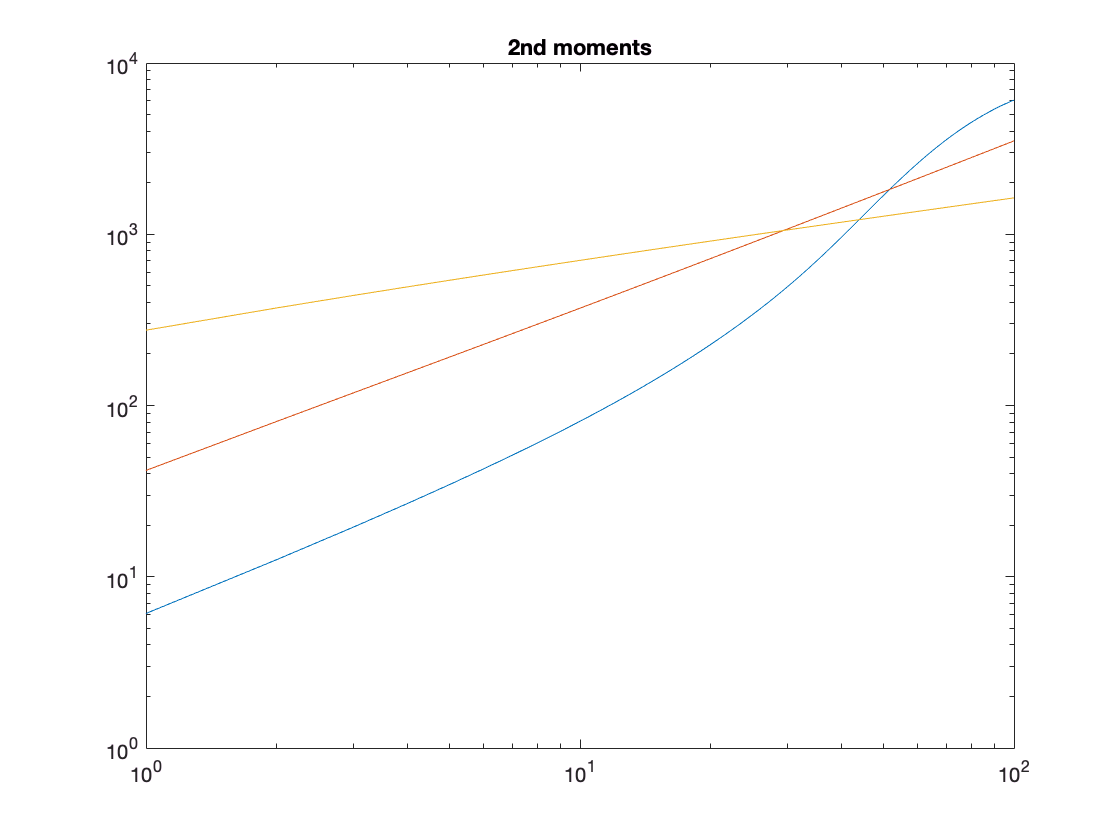

clf
n=3; % 3 means the second moment
loglog(t/24/3600, (lung_moments(:,n).^(1/3) - r0^(2/3)))
hold all
loglog(t/24/3600, (rich_moments(:,n).^(1/3) - r0^(2/3)))
loglog(t/24/3600, (rayl_moments(:,n).^(1/3) - r0^(2/3)))
title('2nd moments')

cdf_rich = 2*pi*dr*cumsum(r'.*Prich,1);
cdf_lung = 2*pi*dr*cumsum(r'.*Plung,1);
cdf_rayl = 2*pi*dr*cumsum(r'.*Prayl,1);

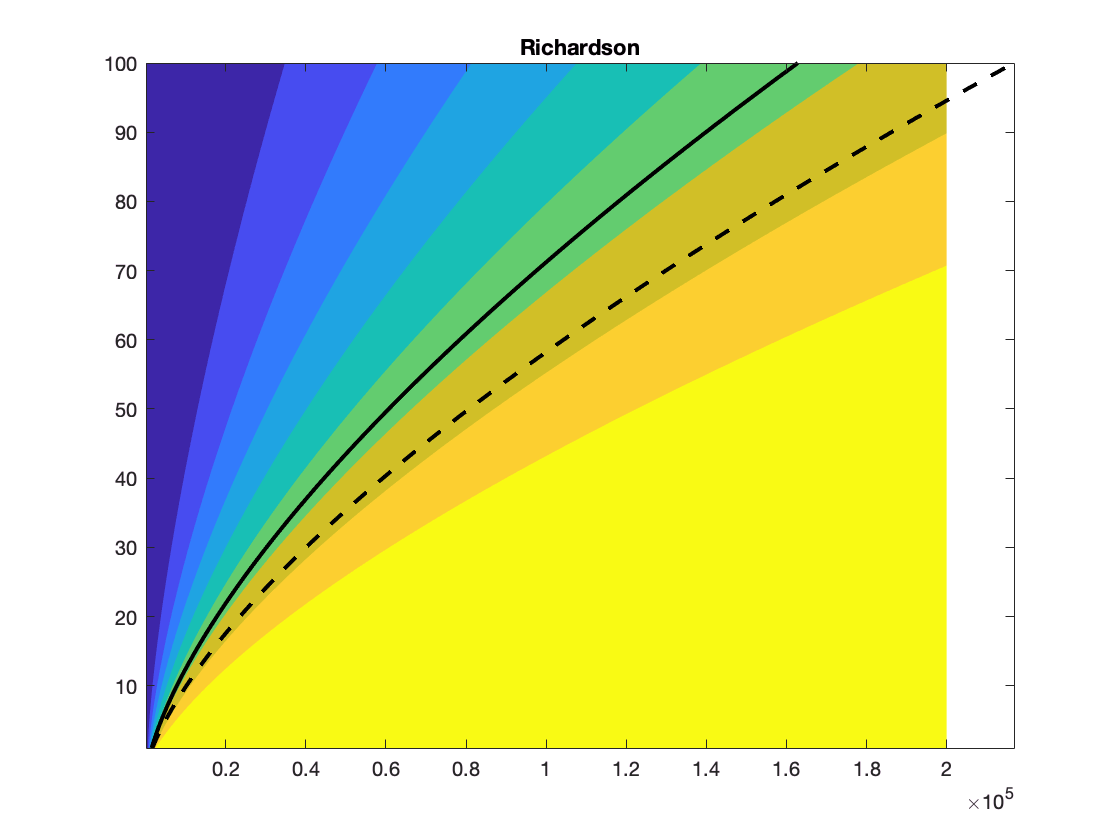

clf
id = find(r<=200e3, 1, 'last'); 
levels=linspace(0,1,10);
contourf(r(1:id),t/24/3600, cdf_rich(1:id,:)', levels,'edgecolor','none')
hold all 
%plot(rich_moments(:,1), t, 'linewidth', 2, 'color', 'k')
plot(rich_moments(:,2), t/24/3600, 'linewidth', 2, 'color', 'k')
plot(rich_moments(:,3).^0.5, t/24/3600, '--', 'linewidth', 2, 'color', 'k')
%xlim([0,100e3])
title('Richardson')

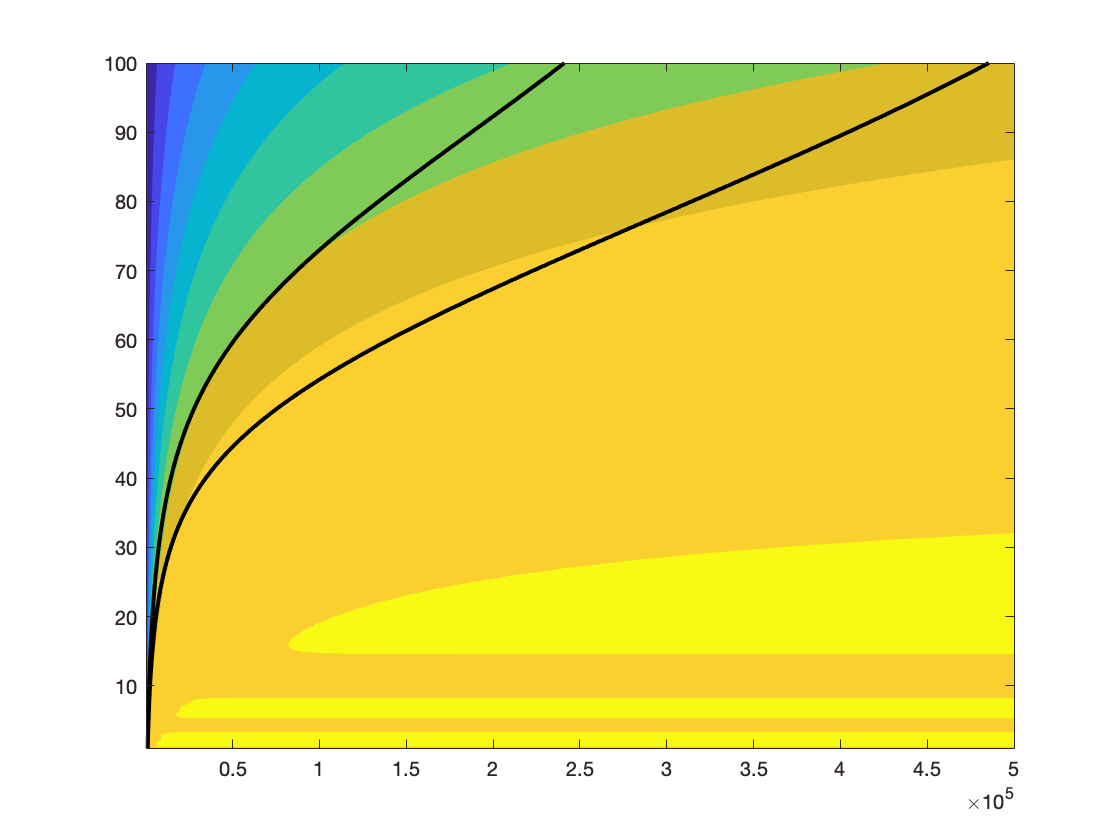

clf
id = find(r<=500e3, 1, 'last'); 
contourf(r(1:id),t/24/3600, cdf_lung(1:id,:)',levels, 'edgecolor','none')
hold all 
%plot(rich_moments(:,1), t, 'linewidth', 2, 'color', 'k')
plot(lung_moments(:,2), t/24/3600, 'linewidth', 2, 'color', 'k')
plot(lung_moments(:,3).^0.5, t/24/3600, 'linewidth', 2, 'color', 'k')

%xlim([0,100e3])

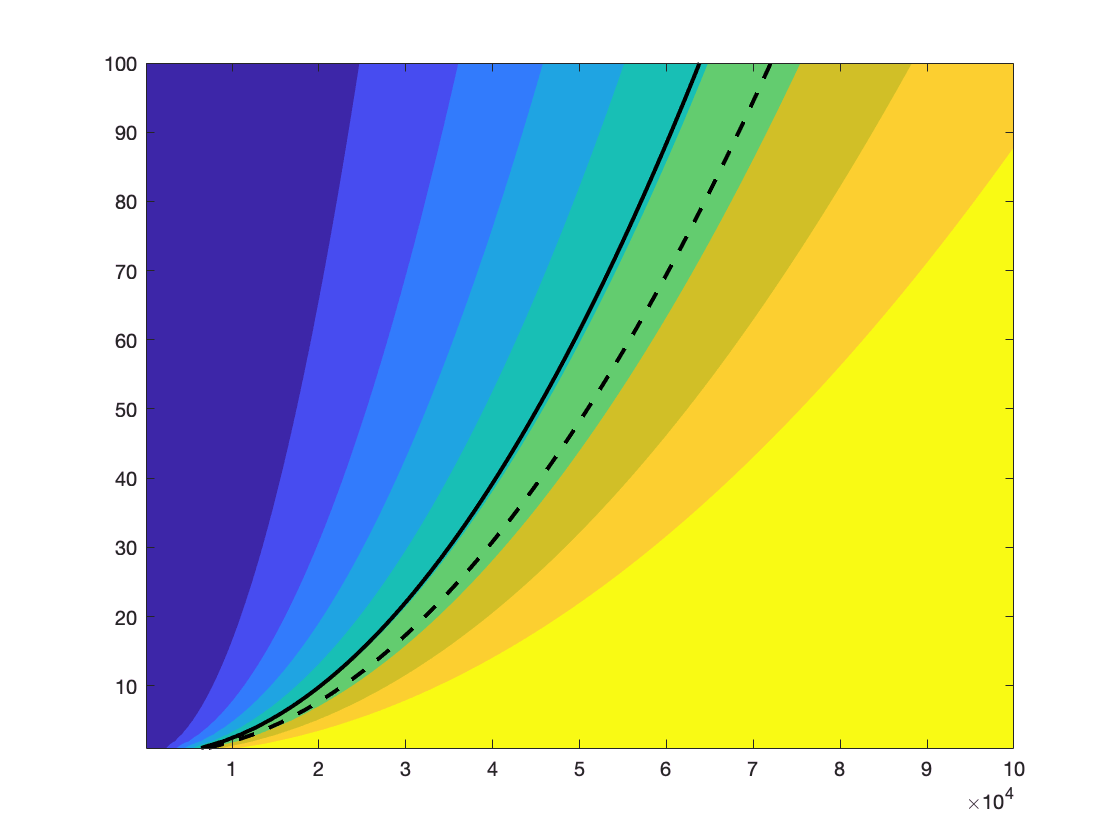

clf
id = find(r<=100e3, 1, 'last'); 
contourf(r(1:id),t/24/3600, cdf_rayl(1:id,:)', levels,'edgecolor','none')
hold all 
%plot(rich_moments(:,1), t, 'linewidth', 2, 'color', 'k')
plot(rayl_moments(:,2), t/24/3600, 'linewidth', 2, 'color', 'k')
plot(rayl_moments(:,3).^0.5, t/24/3600,'--', 'linewidth', 2, 'color', 'k')

%xlim([0,100e3])

## Functions

function [mom] = moments(P, n, r)
    mom = 2*pi*trapz(r, P'.*r.^(n+1), 2);
end